map = load("multilayerMap.mat").map;

binaryMap = map(:,:,1);
speedMap = map(:,:,2);
trafficMap = map(:,:,3);
obstacleMap = map(:,:,4);

Binary Map Display

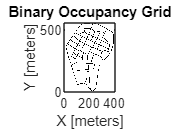

binaryOccMap = binaryOccupancyMap(binaryMap);
show(binaryOccMap)

Speed Limit Cost Map

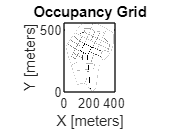

costMap_normalized = speedMap./max(max(speedMap));
speedOccMap = occupancyMap(costMap_normalized);

show(speedOccMap)

Traffic Intensity

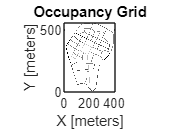

trafficMap_normalized = trafficMap./max(max(trafficMap));
trafficOccMap = occupancyMap(trafficMap_normalized);

show(trafficOccMap)

Obstacle Map

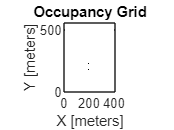

obstacleMap_normalized = obstacleMap./max(max(obstacleMap));
obstacleOccMap = occupancyMap(obstacleMap_normalized);

show(obstacleOccMap)

Full Cost Map

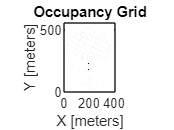

cost = speedMap .* trafficMap + obstacleMap;

costMap_normalized = cost./max(max(cost));
costOccMap = occupancyMap(costMap_normalized);

show(costOccMap)

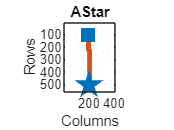

[startPoint, stopPoint] = startStopGenerator(binaryMap);
planner = plannerAStarGrid(costOccMap);
plan(planner,startPoint,stopPoint);
show(planner)

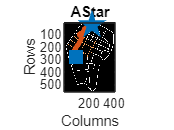

test_map = costMap_normalized*0.99;
test_map(test_map==0) = 1;
testOccMap = occupancyMap(test_map);

[startPoint, stopPoint] = startStopGenerator(binaryMap);
planner = plannerAStarGrid(testOccMap);
path = plan(planner,startPoint,stopPoint);
show(planner)

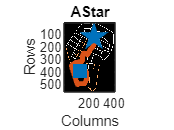

ans =    386   130
   386   131
   386   132
   386   133
   386   134
   386   135
   386   136
   386   137
   386   138
   386   139


[startPoint, stopPoint] = startStopGenerator(binaryMap);
task_1(map, startPoint, stopPoint)